[audioIn, fs] = audioread('enhanced_audio.mp3');

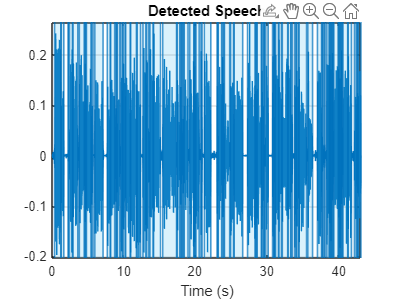

windowDuration = 0.005; % seconds
numWindowSamples = round(windowDuration * fs);
win = hamming(numWindowSamples, 'periodic');

percentOverlap = 29;
overlap = round(numWindowSamples * percentOverlap / 100);

mergeDuration = 0.05;
mergeDist = round(mergeDuration * fs);

detectSpeech(audioIn(:, 1), fs, "Window", win, "OverlapLength", overlap, "MergeDistance", mergeDist)